# Task:  **Lagrangian approach for deriving Eoms for a 3D pendulum**

In this task we're going to look at how the Lagrangian Dynamics approach can be used to derive the equations of motion of a 3D-pendulum.  Steps that we'll take will include:

- What is a PASSIVE rotation matrix ?

- How do i construct a Direction Cosine Matrix (DCM) from a given rotation sequence ?

- What is the relationship between BODy rates and EULER rates ?

- apply Lagrange's equation to derive the sytem EoMs

## Euler-Lagrange equations:

The Euler-Lagrange formula will be used to derive the equations of motion for a Rigid Body, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terms of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 28-Aug-2016, bradley.horton@mathworks.com.au`

# **Prework - part A :   Euler angles and Euler rates**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

Assume that we orientate a body in space via 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

Two key concepts described in the above script are:

- 
$$A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{\omega_x \cr \omega_y \cr \omega_z}  $$


- $\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$      where     $\bf ^BR_G = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z)$

We have implemented the calculations for $\bf ^BR_G$ and  **A **into the Live Function `bh_func_calc_euler_bRg_ZYX`

syms phi theta psi
 
if( "2018a" == string( version('-release')))
    [bRg, A] = bh_func_calc_euler_bRg_ZYX()    
else
    [bRg, A] = LOC_collect_euler_concepts()
end            

## Introducing the 3D pendulum:

Our 3D pendulum looks like this:

##   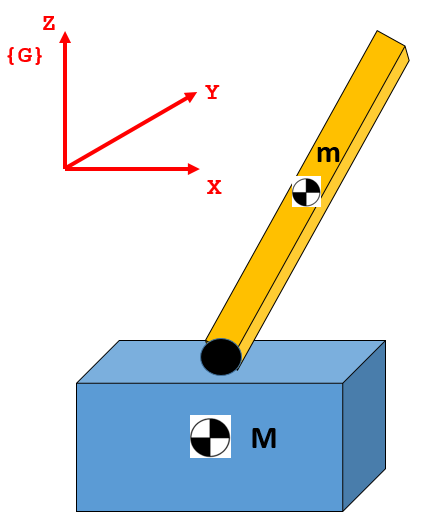     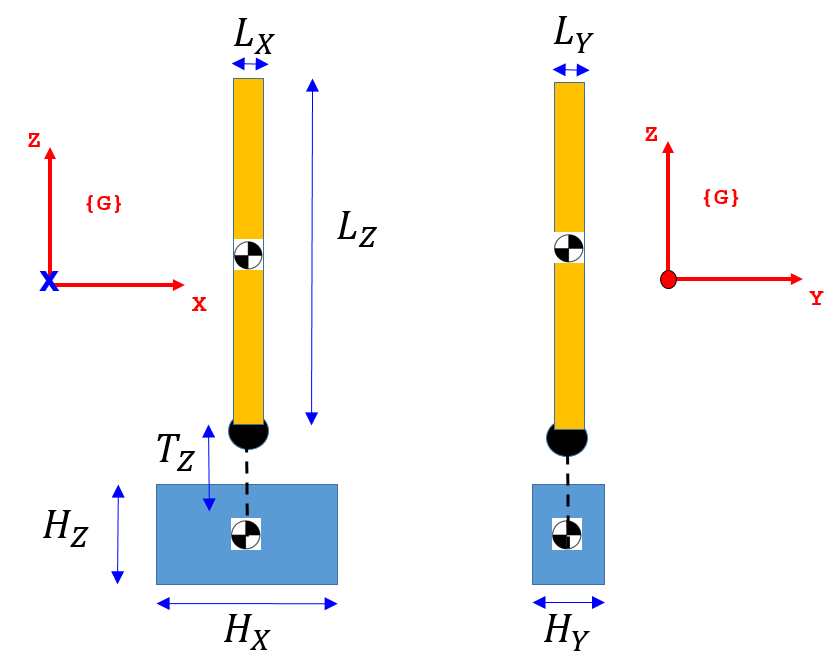

- The pendulum is attached to the base cart via a spherical joint.  

- The sperical joint permits the pendulum to yaw, pitch and roll.  

- The base cart may translate in the inertial X,Y, and Z directions.

- We will be applying forces to the Base cart only

- We will represent the base cart as a point mass.

## Defining the some model parameters:

syms  m_pend  M_cart g
syms  Tv_Z  Lx  Ly  Lz

## Defining the pendulum INERTIA:

So let's define the INERTIA matrix for the pendulum about its body fixed **center of mass** frame:

   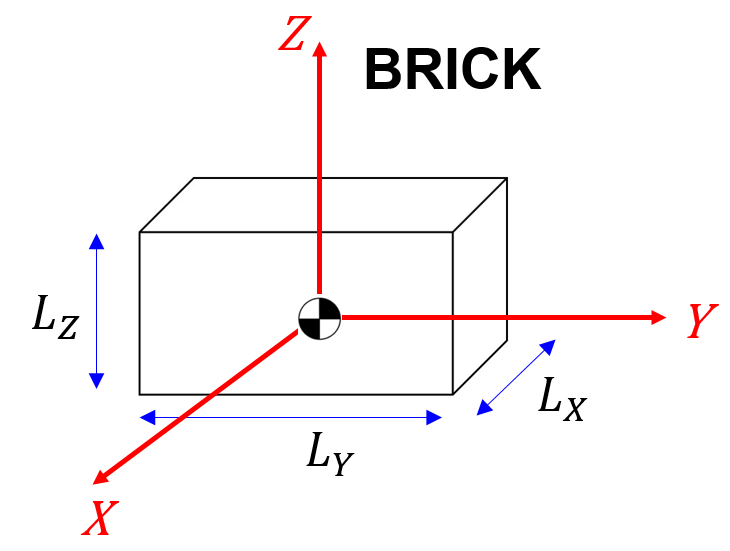

I_pend = ...
      m_pend *[    (Ly^2 + Lz^2)/12,    0,                    0; ...
                    0,                 (Lx^2 + Lz^2)/12,      0; ...
                    0,                  0,                   (Lx^2 + Ly^2)/12;] ; 

## Euler angles for the pendulum:

syms        Phi(t)      Theta(t)       Psi(t)    
syms    THE_Phi     THE_Theta      THE_Psi

INERTIAL {G}-frame co-ordinates for the BASE cart and the FORCES on the cart:

syms            X(t)        Y(t)         Z(t)
syms        THE_X       THE_Y        THE_Z
syms         Fg_X        Fg_Y         Fg_Z 

Define the Direction Cosine matrix using our NEW pendulum angle symbols:

bRg = subs(bRg, [phi, theta, psi],[Phi(t)      Theta(t)       Psi(t)])

Define the Pendulum's angular velocity using our NEW symbols:

                  % OLD_list          NEW_list
A       = subs(A, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)]);

e_dot   = [ diff(Phi(t),   t);
            diff(Theta(t), t); 
            diff(Psi(t),   t) ]

w_pend  = A * e_dot      

## Define the Cart's Kinetic and Potential energy:

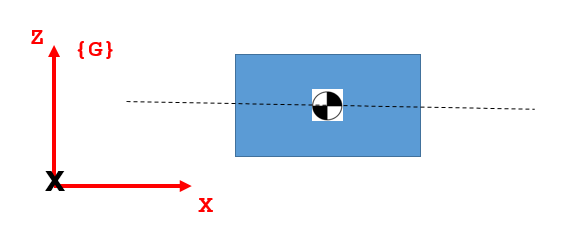

v_col = [diff(X(t),t); diff(Y(t),t); diff(Z(t),t);];

KE_cart = (1/2)* v_col.'  * M_cart * v_col;
PE_cart = M_cart*g*Z(t);

## Define the Pendulum's Kinetic and Potential energy:

 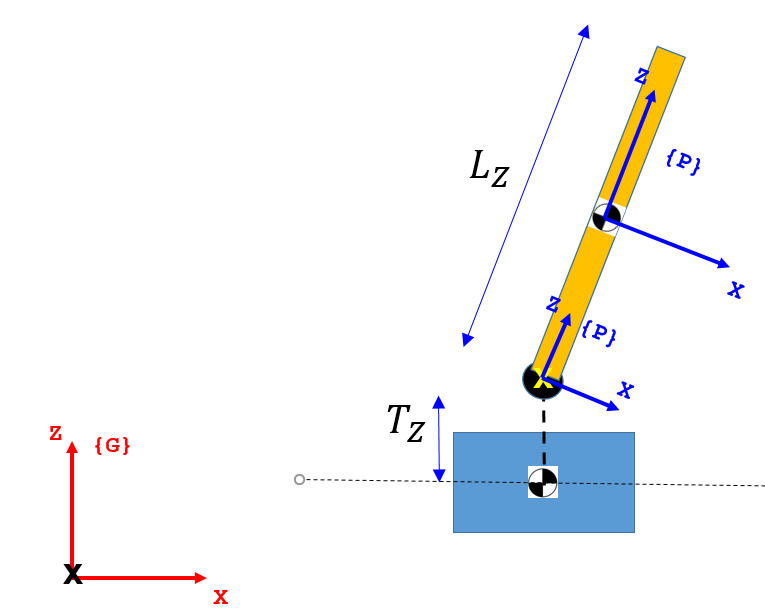

The position of the pendulum's center of mass according to a BODY FIXED frame attached to the sperical joint is:

rp = [0;0;Lz/2];

Therefore, the position of the pendulum's centre of mass according to the {G}-frame is:

gRb     = bRg.';
rg_tmp  = gRb * rp

rg = [X(t); Y(t); Z(t)]  +  [0;0;Tv_Z]   +   rg_tmp;

So the translational velocity of the Pendulum's centre of mass is:

vcg_pend_col = diff(rg, t);

So the **Pendulum's Potential**** Energy** is:

PE_pend = m_pend*g*rg(3);

So the **Pendulum's Kinetic**** Energy** is:

KE_pend = (1/2)* vcg_pend_col.' * m_pend * vcg_pend_col   + ...
          (1/2)* w_pend.'       * I_pend * w_pend

## **The *****SYSTEM***** Kinetic and Potential energy:**

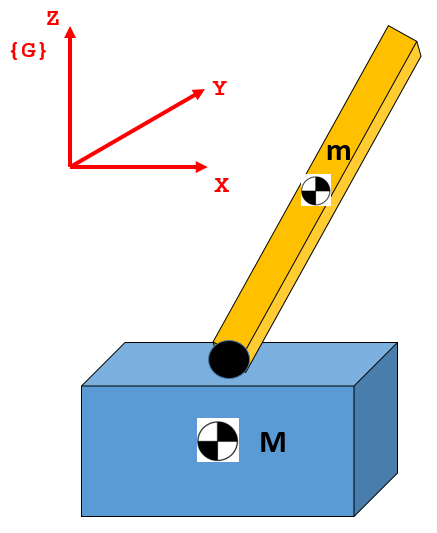

KE = KE_cart  +  KE_pend;
PE = PE_cart  +  PE_pend;

# Prepare for the Computation of the Generalised Forces:

Shortly we'll calculate the generalised force *Q* :

# Apply Lagrange's equation - part 1 

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 
$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $$
 

Where:

- *L = KE - PE, *is our system lagrangian

- $q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ} \}$ are the generalised co-ordinates 

- $Q_k$ are the generalised forces (Forces and Torques) for our system

Recall our list of generalised co-ordinates:

actual_list_SYM_pos = [    Phi(t),      Theta(t),       Psi(t),        X(t),       Y(t),      Z(t)];
holder_list_SYM_pos = [THE_Phi,     THE_Theta,      THE_Psi,       THE_X       THE_Y      THE_Z   ];

Now let's create a Lagrangian object using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

And let's compute the system's equations of motion:

lag_OBJ = lag_OBJ.calc_eom()

So what do the equations of motion actually look like ? - they are long equations involving many terms

lag_OBJ.show_eom()

If you want to look at an individual equation of motion (eg: the LHS of the $4\mathrm{th}$ equation), then you could do this:

lag_OBJ.get_eom(4, 'actual', 'LHS')

In a moment we'll show how to "collect" the terms in these EOMs and present them in a format that looks like this:

- 
$$M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$$


# Apply Lagrange's equation - part 2 

Define all of the active forces acting on the system.  NOTE - we won't include the force of gravity here ... because we have already catered for the effect of gravity via the system POTENTIAL energy.


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


So we need to define the forces AND the velocity of the point where the forces are applied.  In our case we'll assume that the forces applied to the cart are applied at the cart's center of mass:

v_col = [ diff(X(t),t);   diff(Y(t),t);    diff(Z(t),t);]

F_mat = [   Fg_X,       0,        0;
               0,    Fg_Y,        0;
               0,       0,     Fg_Z;    ];
          
v_mat = [  v_col,   v_col,     v_col    ];

Create a generalised force object using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( F_mat, ...
                               v_mat, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                 

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

**Absorb the Generalised Forces****:** We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then recalculate the equations of motion:  

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

 Now echo our equations:

lag_OBJ.show_eom( )

# Isolate the term of interest  M,C,K,G

We can express our system equations of motion in the following form:


$$M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()
fh_BOUNDARY = @(txt)fprintf('\n %s \n Here is the %s matrix: \n',repmat('#',1,75),txt);

Here's **M**:

fh_BOUNDARY('M');  res_T.M

Here's **C**:

fh_BOUNDARY('C');  res_T.C

Here's **K**:

fh_BOUNDARY('K');  res_T.K

Here's **G**:

fh_BOUNDARY('G');  res_T.G

Here's **Q**:

fh_BOUNDARY('Q');  res_T.Q

# Convert symbolic EoM expressions into a block diagram model

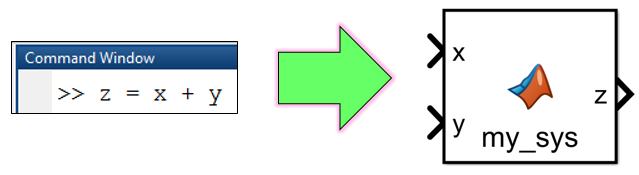

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks()

# **Local functions:**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

The function below runs the above script and returns some of the symbols defined in the script.  When we call the script from inside the function, the variables created by the script are created in the "local" function workspace.

function [bRg, A] = LOC_collect_euler_concepts()
    
    % run the script inside our function
    bh_review_Euler_rates_and_wb
    
end